# 複数競技の統一的モデル：シミュレーション(2)

## 平均得点から勝率を求める

clear;clc;close all;

1試合を構成する小さな試合単位の数を大きく設定する

N=1000;

両チームの平均得点

参考：様々な種目の平均得点(主要な国際大会を調査)

- サッカー：1.5点

- ホッケー：3点

- 水球：12点

- ハンドボール：28点

- バスケットボール：75点

muA=75;muB=70;
% muA=1.5;muB=1.3;
%%
 
x=1;pa=muA/N;pb=muB/N;p0=1-pa-pb;
for n1=1:N
    x=conv(x,[pb p0 pa]);
end
xlim_min=max(find(cumsum(x)<0.001));
xlim_max=min(find(cumsum(x)>1-0.001));

figure;
tiledlayout(3,1);
nexttile([2,1]);
winMask=ones(2*N+1,1);winMask(1:N+1)=0;
drawMask=zeros(2*N+1,1);drawMask(N+1)=1;
loseMask=ones(2*N+1,1);loseMask(N+1:2*N+1)=0;
grid on;set(gca,'fontname','メイリオ');hold on;
bar(-N:N,x'.*loseMask,'BarWidth',1,'EdgeColor','w','FaceAlpha',0.5);
bar(-N:N,x'.*drawMask,'BarWidth',1,'EdgeColor','w','FaceAlpha',0.5);
bar(-N:N,x'.*winMask,'BarWidth',1,'EdgeColor','w','FaceAlpha',0.5);
legend({'負け','分け','勝ち'},'Location','northoutside','Orientation','horizontal');
xlim(-N+[xlim_min, xlim_max]);
xlabel('得点差');
ylabel('確率')
nexttile;
plotData=[sum(x(1:N)) x(N+1) sum(x(N+2:end))]

plotData =     0.3239    0.0304    0.6457


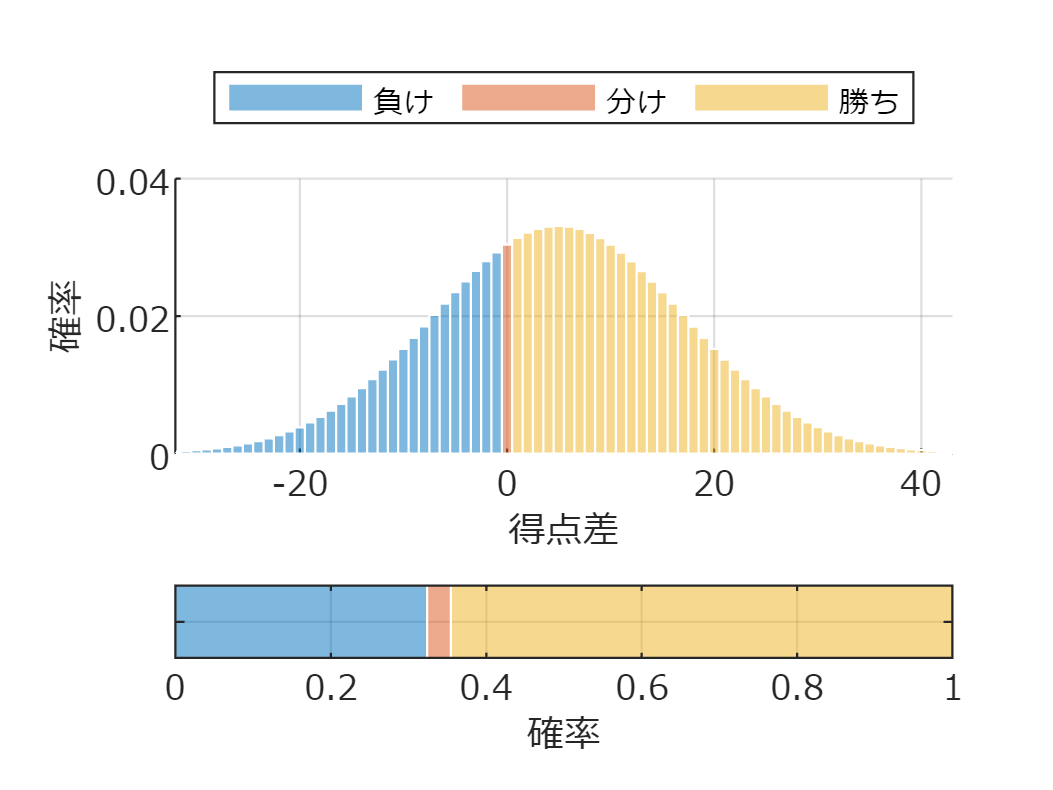

plotData=[plotData;plotData];
barh(plotData,'stacked','BarWidth',1,'EdgeColor','w','FaceAlpha',0.5);
ylim([0.5 1.5]);xlim([0 1]);
grid on;set(gca,'fontname','メイリオ');hold on;
yticklabels([]);
xlabel('確率');

exportgraphics(gcf,'fig_unifiedModelSimulation02.pdf');